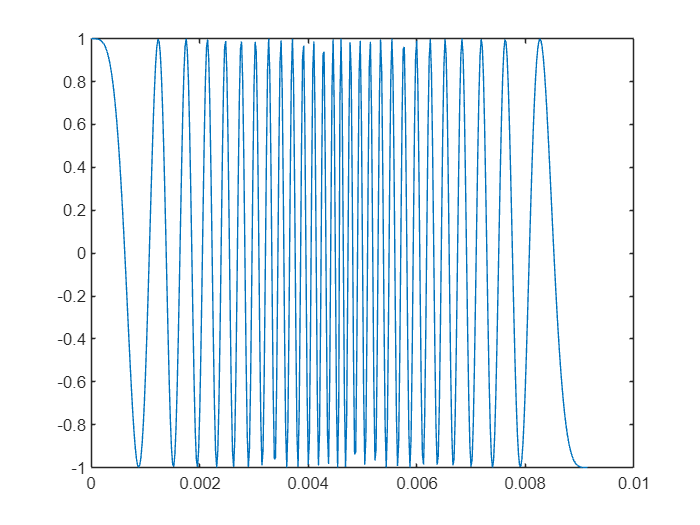

sample_rate = 48000;
preamble_sample = 220;
preamble_time = preamble_sample / sample_rate;
t = 0:1/sample_rate:13;
f = [8*10^3, 810*10^3];
% preamble = [chirp(t(1:preamble_sample), f(1), preamble_time, f(2)), chirp(t(1:preamble_sample), f(2), preamble_time, f(1))];
audio = audioread("abc.wav")';
preamble = audio(48001:48000+preamble_sample * 2);

plot(t(1:2 * preamble_sample), preamble);

% recive_preamble = [zeros(1,int32(rand()*200)), preamble, zeros(1,int32(rand()*100))];

recive_preamble = audioread("rec.wav")';
recive_preamble = recive_preamble(1, :);
% recive_preamble = [zeros(1,400), audio_rec, zeros(1,400)];
N = length(recive_preamble)

N = 564480

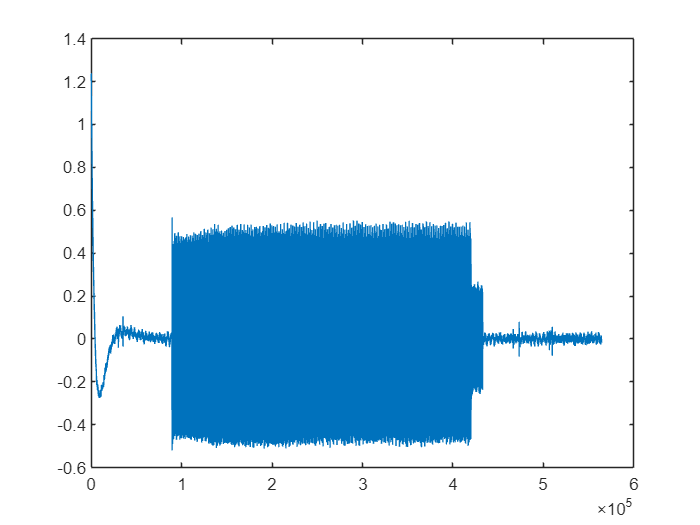

plot(recive_preamble);

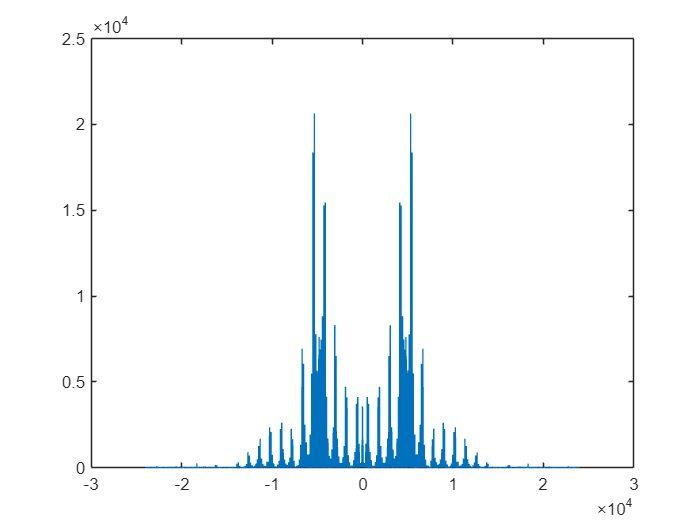

plot(48000 / N * (-N/2:N/2-1), abs(fftshift(fft(recive_preamble))));

% recive_preamble = bandpass(recive_preamble, [2 9000], 48000)
plot(48000 / N * (-N/2:N/2-1), abs(fftshift(fft(recive_preamble))))

corrs = zeros(1, length(recive_preamble));
power = zeros(1, length(recive_preamble));
power_smoothed = zeros(1, length(recive_preamble));
recive_window = zeros(1, preamble_sample * 2);
smooth_factor = 1 / 128;
for i = 1:length(recive_preamble)
    sample = recive_preamble(i);
    power(i) = sample * sample;
    
    if i == 1
        power_smoothed(i) = smooth_factor * power(i);
    else
        power_smoothed(i) = smooth_factor * power(i) + (1 - smooth_factor) * power_smoothed(i - 1);
    end
    
    % add sample to window
    recive_window = [recive_window(2:preamble_sample * 2), sample];
    corrs(i) = sum(preamble .* recive_window) / preamble_sample / 2;
end
plot(recive_preamble)

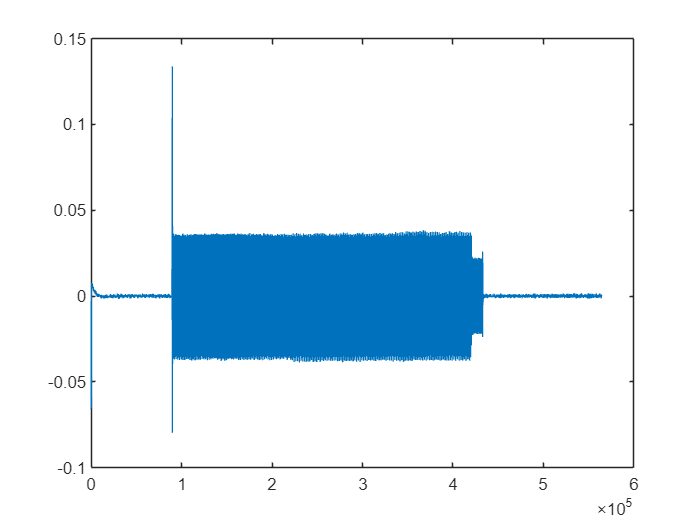

plot(corrs);

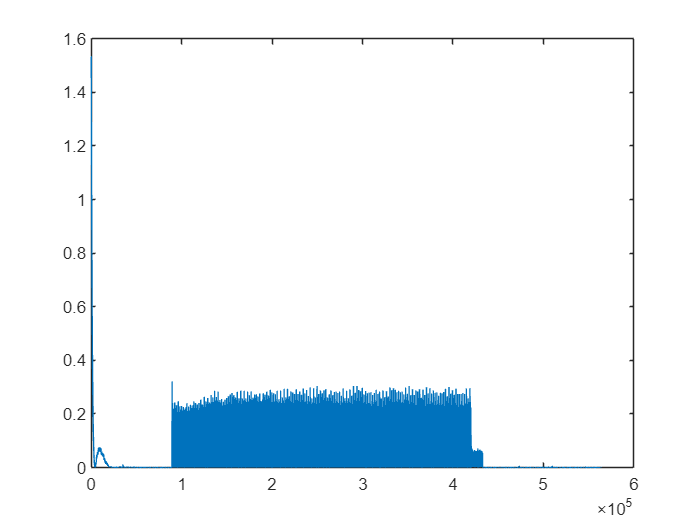

plot(power);

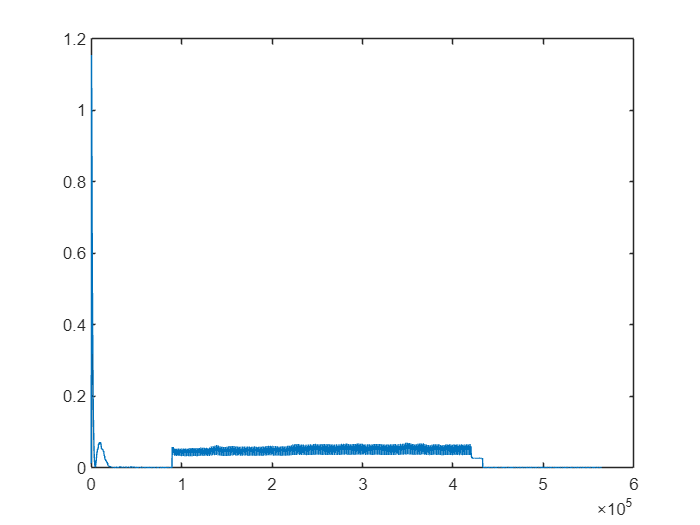

plot(power_smoothed);

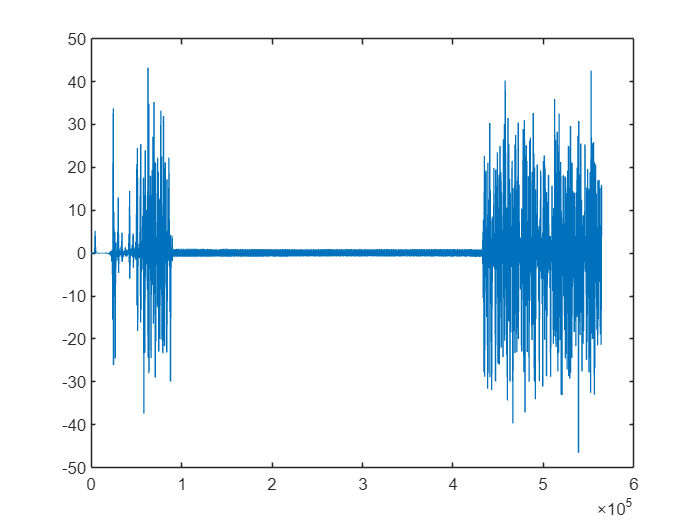

plot(corrs ./ power_smoothed )